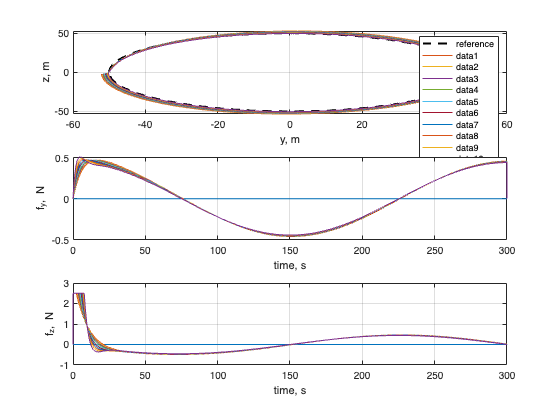

Iteration 01: posErr3D = 3.2961
Iteration 02: posErr3D = 2.963
Iteration 03: posErr3D = 2.6364
Iteration 04: posErr3D = 2.3163
Iteration 05: posErr3D = 2.003
Iteration 06: posErr3D = 1.6976
Iteration 07: posErr3D = 1.4017
Iteration 08: posErr3D = 1.1184
Iteration 09: posErr3D = 0.85343
Iteration 10: posErr3D = 0.62175


% ulrich 2017

% NUMERICAL EXAMPLE (ref. section III.C)

% constants
mu  = 398600;  % km^3/s^2
O33 = zeros(3,3);
I33 = eye(3);

% parameters
m    = 20;  % kg
a    = 7200;  % km
f    = 240;  % Hz
dt   = 1/f;  % s
Fmax = 2.5;  % N

% reference trajectory 1
tf = 300;  % s
t  = 0:dt:tf;
r  = 50;

yd = [0*t; -r*cos(2*pi*t/tf); r*sin(2*pi*t/tf)];
x0 = [  0;                -r;                 0; ... 
        0;                 0;                 0];

% % reference trajectory 2
% tf = 300;  % s
% r  = 50;   % m
% Fa = 1.0;  % N, allocated force 
% 
% v1 = 2*pi*r/tf;
% t1 = m*v1/Fa;
% 
% t  = 0:dt:(300+floor(t1));
% 
% yd = zeros(3,length(t));
% x0 = [  0;                -r;                 0; ... 
%         0;                 0;                 0];
% 
% for k = 1:length(t)
%     tk = t(k);
% 
%     if tk < t1
%         s = 0.5 * Fa/m * tk^2;
%     else
%         s = 0.5 * Fa/m * t1^2 + v1 * (tk-t1);
%     end
% 
%     alpha = s/r;
% 
%     yd(2,k) = -50*cos(alpha);
%     yd(3,k) =  50*sin(alpha);
% end

figure;
subplot(3,1,1);
title('trajectory');
plot( yd(2,:), yd(3,:), 'k--', 'LineWidth', 2 );
xlabel('y, m');
ylabel('z, m');
legend('reference');
grid on;
hold on;

% state-space -- double-integrator
A = [O33 I33; ...
     O33 O33];
B = [O33; ...
     I33/m];
C = [I33 O33];
D = O33;
sys2i = c2d(ss(A,B,C,D),dt);

% state-space -- clohessy-wiltshire
w = sqrt(mu/a^3);
Acw = [O33 I33; ...
       3*w^2 0    0    0 2*w 0; ...
       0     0    0 -2*w   0 0; ...
       0     0 -w^2    0   0 0];
sysCW = c2d(ss(Acw,B,C,D),dt);

% PD controller
kp = [0.172     0     0; ...
      0     0.172     0; ...
      0         0 0.100];

kd = [4 0 0; ...
      0 4 0; ...
      0 0 3];

% loop initialization
u      = zeros(3,length(t));
x      = zeros(6,length(t));
x(:,1) = x0;

% y-axis control signal figure
subplot(3,1,2);
title('control')
plot(t,u(2,:));
xlabel('time, s');
ylabel('f_y, N');
grid on;
hold on;

% y-axis control signal figure
subplot(3,1,3);
title('control')
plot(t,u(2,:));
xlabel('time, s');
ylabel('f_z, N');
grid on;
hold on;

% switch confidence level factor
% 1 - constant beta
% 2 - varying beta
clfSwitch = 2;

% number of iterations
N = 10;

for j = 1:N  % iteration loop

    % fixed or variable confidence level factor
    switch (clfSwitch)
        case 1
            beta = 1;
        case 2
            beta = (j-1)/N;  % we use beta_{j}, not beta_{j+1}
            % if j <= N
            %     beta = (j-1)/N;
            % else
            %     beta = 1;
            % end
        otherwise
            error('Invalid clfSwitch value');
    end

    for k = 1:(length(t)-1)  % timestep loop

        % control error; state was calculated in the _previous_ timestep
        e = yd(:,k) - sysCW.c * x(:,k);

        % control command has three parts: learning, proportional...
        u(:,k) = beta * u(:,k) + kp * e;
 
        % ...and derivative
        if k > 1
            e0 = yd(:,k-1) - sysCW.c * x(:,k-1);
            u(:,k) = u(:,k) + kd * (e-e0) / dt;
        end

        % apply saturation condition
        for i = 1:3  % axis loop
            u(i,k) = min( Fmax, max( -Fmax, u(i,k) ) );
        end

        % state at the _next_ timestep
        x(:,k+1) = sysCW.a * x(:,k) + sysCW.b * u(:,k);

    end

    % print average 3D position error
    posErr3D = mean( vecnorm( x(1:3,:)-yd ) );
    disp( ['Iteration ' num2str(j,'%02i') ': posErr3D = ' num2str(posErr3D) ] );

    % plot trajectory on existing figure
    subplot(3,1,1);
    plot( x(2,:), x(3,:) );

    % plot y-control on existing figure
    subplot(3,1,2);
    plot( t, u(2,:));

    % plot z-control on existing figure
    subplot(3,1,3);
    plot( t, u(3,:));

end